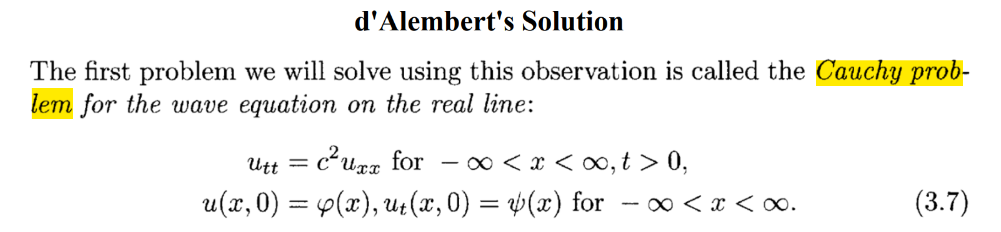

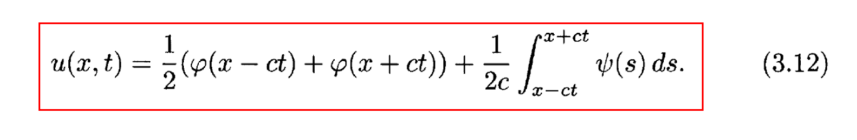

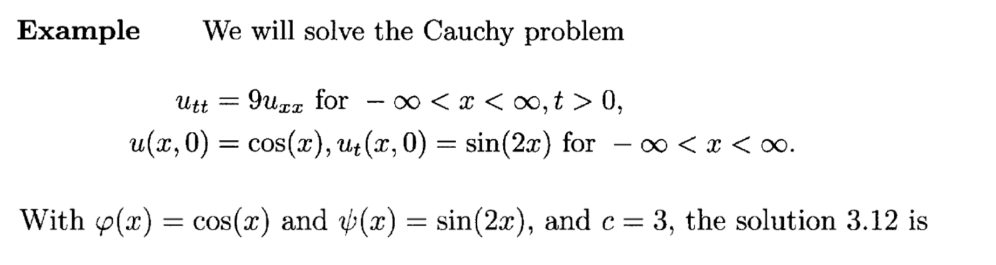

clear
clc
syms x t u(x,t) phi(x) psi(x)
c = 3;
WaveWq = c^2*diff(u,x,2) == diff(u,t,2)

$$WaveWq(x, t) = 9\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)$$

t0 = u(x,0) == cos(x)

$$t0 = u\left(x,0\right)=\cos\left(x\right)$$

Dt = diff(u,t);
Dt0 = Dt(x,0) == sin(2*x)

$$Dt0 = \left({\left(\frac{\partial }{\partial t}u\left(x,t\right)\right)|}_{t=0}\right)=\sin\left(2\,x\right)$$

phi(x) = rhs(t0); psi(x) = rhs(Dt0);
u1 = (phi(x-c*t)+phi(x+c*t))/2

$$u1 = \frac{\cos\left(3\,t+x\right)}{2}+\frac{\cos\left(3\,t-x\right)}{2}$$

u2 = int(psi,x,[x-c*t x+c*t])/(2*c)

$$u2 = \frac{{\sin\left(3\,t+x\right)}^{2}}{6}-\frac{{\sin\left(3\,t-x\right)}^{2}}{6}$$

u(x,t)  = simplify(u1+u2)

$$u(x, t) = \frac{\cos\left(3\,t\right)\,\cos\left(x\right)\,\left(2\,\sin\left(3\,t\right)\,\sin\left(x\right)+3\right)}{3}$$

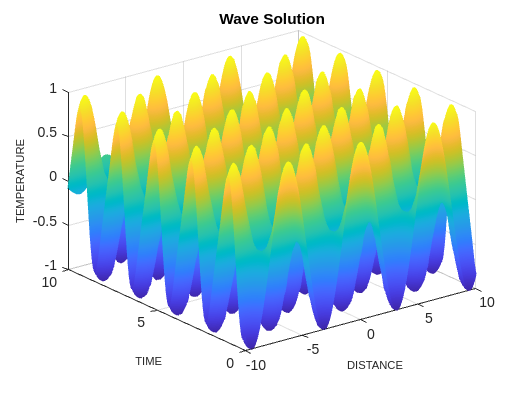

clf; figure
fsurf(u,[-10 10 0 10],"EdgeColor","interp")
title("Wave Solution")
xlabel('DISTANCE','Fontsize',8)
ylabel('TIME','Fontsize',8)
zlabel('TEMPERATURE','Fontsize',8)

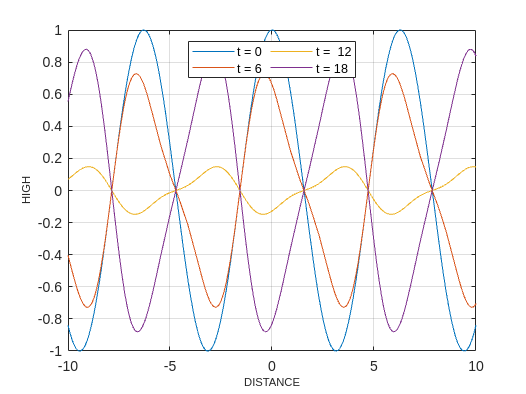

clf
tm = [0 6 12 18];
for i = 1:length(tm)
    sn  = matlabFunction(u(x,tm(i)));
    fplot(sn,[-10 10])
    grid on, hold on
end
xlabel('DISTANCE','FontSize',8);
ylabel('HIGH','FontSize',8)
legend('t = 0','t = 6','t =  12','t = 18','Location','north','NumColumns',3)

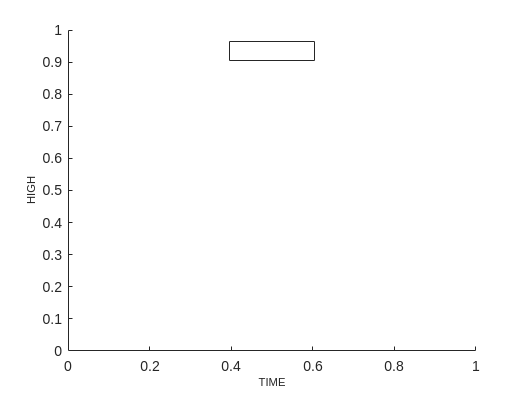

clf
dst = [1 5 9 ];
for i = 1:length(dst)
   % sn  = matlabFunction(u(dst(1),tm(i)));
   % fplot(sn,[0 10])
   % grid on, hold on
end
xlabel('TIME','FontSize',8);
ylabel('HIGH','FontSize',8)
legend('dst=1','dst=5','dst=9' ,'Location','north','NumColumns',3)

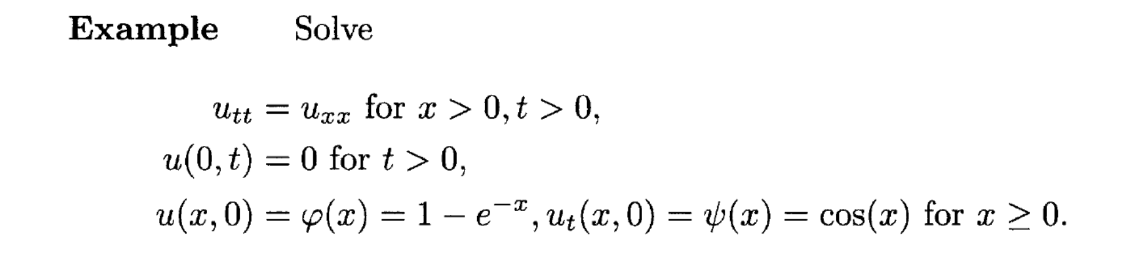

clear
clc
syms x t u(x,t) phi(x) psi(x)
c = 1;
WaveWq = c^2*diff(u,x,2) == diff(u,t,2)

$$WaveWq(x, t) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)$$

t0 =u(x,0) == 1-exp(-x)

$$t0 = u\left(x,0\right)=1-{\mathrm{e}}^{-x}$$

Dt = diff(u,t)

$$Dt(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)$$

Dt0 = Dt (x,0) == cos(x)

$$Dt0 = \left({\left(\frac{\partial }{\partial t}u\left(x,t\right)\right)|}_{t=0}\right)=\cos\left(x\right)$$

phi(x) = rhs(t0); psi(x) = rhs(Dt0);

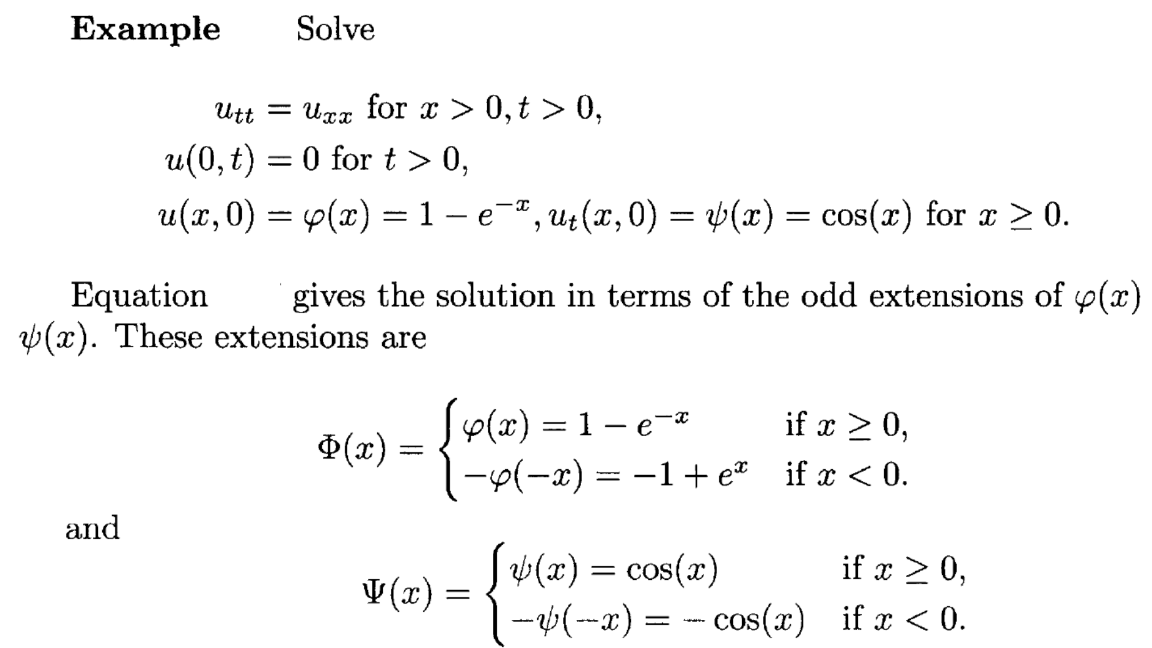

**Case 1.  x-t >0**

assume (x>t)
u1 = (phi(x-c*t)+phi(x+c*t))/2

$$u1 = 1-\frac{{\mathrm{e}}^{-t-x}}{2}-\frac{{\mathrm{e}}^{t-x}}{2}$$

u2 = int(psi,x,[x-c*t x+c*t])/(2*c)

$$u2 = \cos\left(x\right)\,\sin\left(t\right)$$

u = simplify(u1+u2)

$$u = \cos\left(x\right)\,\sin\left(t\right)-\frac{{\mathrm{e}}^{-t-x}}{2}-\frac{{\mathrm{e}}^{t-x}}{2}+1$$

**Case 2.  x-t <0**

assume (x<t)
u1 = (-phi(-(x-c*t))+phi(x+c*t))/2

$$u1 = \frac{{\mathrm{e}}^{x-t}}{2}-\frac{{\mathrm{e}}^{-t-x}}{2}$$

u2 = (int(-psi,x,[x-c*t 0])+int(psi,x,[0 x+c*t]))/(2*c)

$$u2 = \frac{\sin\left(t+x\right)}{2}-\frac{\sin\left(t-x\right)}{2}$$

u = simplify(u1+u2)

$$u = \frac{{\mathrm{e}}^{x-t}}{2}-\frac{{\mathrm{e}}^{-t-x}}{2}+\cos\left(t\right)\,\sin\left(x\right)$$

%v = children(u)

%vv = cell2sym(v(1))+cell2sym(v(2))

%rewrite(vv,"sinh")


การแกเ wave eqn โดยใช้ ลาปาส

เปลี่ยน time เป็น complex frequency

และแก้สมการ ode

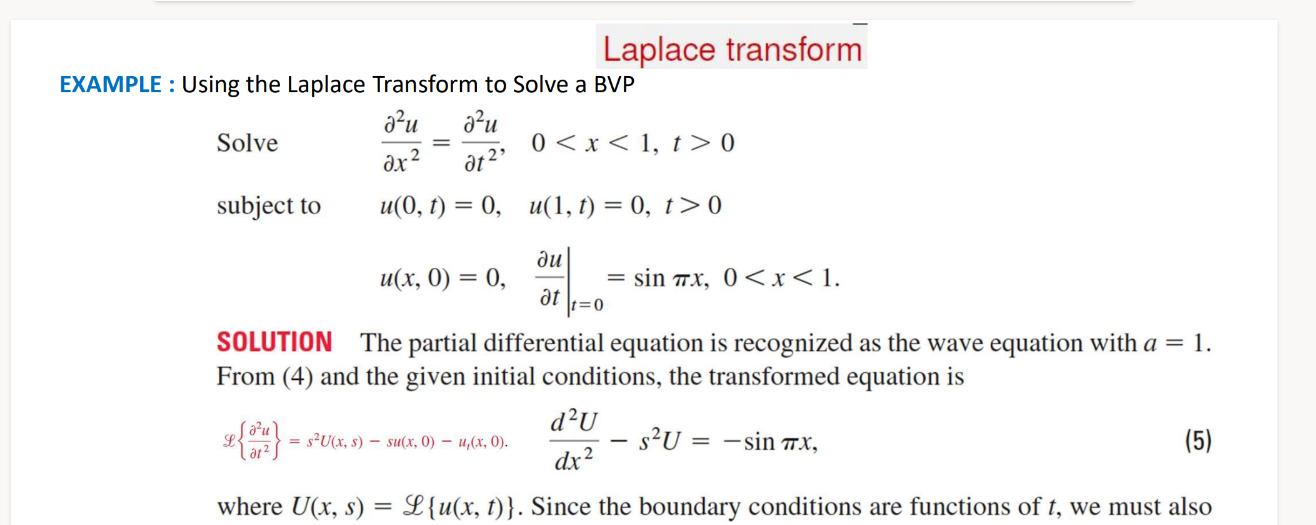

clc; clearvars;
syms x t s u(x,t) U(x,s) Y(x)
Dt = diff(u,t)

$$Dt(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)$$

D2x =diff(u,x,2)

$$D2x(x, t) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

D2t =diff(Dt,t)

$$D2t(x, t) = \frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)$$

eqn = laplace(D2t == D2x,t,s)

$$eqn(x) = s^{2}\,\mathrm{laplace}\left(u\left(x,t\right),t,s\right)-\left({\left(\frac{\partial }{\partial t}u\left(x,t\right)\right)|}_{t=0}\right)-s\,u\left(x,0\right)=\mathrm{laplace}\left(\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right),t,s\right)$$

cond1 = u(0,t) == 0

$$cond1 = u\left(0,t\right)=0$$

cond2 = u(1,t) == 0

$$cond2 = u\left(1,t\right)=0$$

eqn = subs(eqn,{laplace(u,t,s),u(x,0),Dt(x,0),laplace(D2x,t,s)},{U(x,s),0,sin(pi*x),subs(D2x,{u,t},{U,s})})

$$eqn(x) = s^{2}\,U\left(x,s\right)-\sin\left(\pi \,x\right)=\frac{\partial^{2}}{\partial x^{2}}U\left(x,s\right)$$

cond1 = laplace(cond1,t,s) ; cond2 = laplace(cond2,t,s);
cond1 = subs(cond1,laplace(u(0,t),t,s),U(0,s))

$$cond1 = U\left(0,s\right)=0$$

cond2 = subs(cond2,laplace(u(1,t),t,s),U(1,s))

$$cond2 = U\left(1,s\right)=0$$

eqn_n = subs(eqn,U,Y)

$$eqn\_n(x) = s^{2}\,Y\left(x\right)-\sin\left(\pi \,x\right)=\frac{\partial^{2}}{\partial x^{2}}Y\left(x\right)$$

cond_1 = subs(cond1,U,Y);

cond_2 = subs(cond2,U,Y);

sol_g = dsolve(eqn_n)

$$sol\_g = C_{1}\,{\mathrm{e}}^{s\,x}+C_{2}\,{\mathrm{e}}^{-s\,x}+\frac{\pi \,\cos\left(\pi \,x\right)+s\,\sin\left(\pi \,x\right)}{2\,s\,\left(s^{2}+\pi^{2}\right)}-\frac{\pi \,\cos\left(\pi \,x\right)-s\,\sin\left(\pi \,x\right)}{2\,s\,\left(s^{2}+\pi^{2}\right)}$$

sol = dsolve(eqn_n,[cond_1 cond_2])

$$sol = \frac{\sin\left(\pi \,x\right)}{s^{2}+\pi^{2}}$$

sol_t = ilaplace(sol,s,t)

$$sol\_t = \frac{\sin\left(\pi \,t\right)\,\sin\left(\pi \,x\right)}{\pi }$$

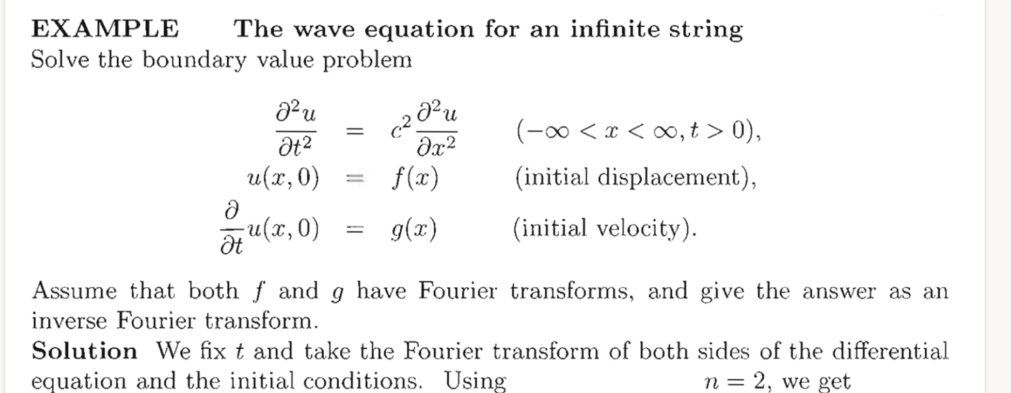

clear
clc
clearvars
syms x t c w u(x,t) U(w,t) Y(t) f(x) g(x) F(w) G(w) cf
Dt = diff(u,t);
D2t = diff(Dt,t);
D2x = diff(u,x,2)

$$D2x(x, t) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

eqn = fourier(D2t == c^2*D2x,x,w)

$$eqn(t) = \mathrm{fourier}\left(\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right),x,w\right)=-c^{2}\,w^{2}\,\mathrm{fourier}\left(u\left(x,t\right),x,w\right)$$

eqn = subs(eqn,{fourier(D2t,x,w),fourier(u,x,w)},{subs(D2t,{u,x},{U,w}),U})

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}U\left(w,t\right)=-c^{2}\,w^{2}\,U\left(w,t\right)$$

eqn = subs(eqn,U(w,t),Y(t));
cond1 =Y(0) == F(w); cond2 = subs(diff(Y(t)),t,0) == G(w);
sol = collect(dsolve(eqn,[cond1 cond2]),[F G]);
var = children(sol)

var = 1×2 cell array
    {[(exp(-c*t*w*1i)/2 + exp(c*t*w*1i)/2)*F(w)]}    {[((exp(-c*t*w*1i)*1i)/(2*c*w) - (exp(c*t*w*1i)*1i)/(2*c*w))*G(w)]}


cof1 = coeffs(cell2sym(var(1)),str2sym('F(w)'))

$$cof1 = \frac{{\mathrm{e}}^{-c\,t\,w\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{c\,t\,w\,\mathrm{i}}}{2}$$

cof2 = coeffs(cell2sym(var(2)),str2sym('G (w)'))

$$cof2 = \frac{{\mathrm{e}}^{-c\,t\,w\,\mathrm{i}}\,\mathrm{i}}{2\,c\,w}-\frac{{\mathrm{e}}^{c\,t\,w\,\mathrm{i}}\,\mathrm{i}}{2\,c\,w}$$

sol = subs(sol,{cof1,cof2},{cos(c*w*t),sin(c*w*t)/(c*w)})

$$sol = \cos\left(c\,t\,w\right)\,F\left(w\right)+\frac{\sin\left(c\,t\,w\right)\,G\left(w\right)}{c\,w}$$

u(x,t) = subs(cf*int(sol*exp(1i*w*x),w,[-inf inf]),cf,str2sym('1/sqrt(2*pi)'))

$$u(x, t) = \frac{\sqrt{2}\,\int_{-\infty }^{\infty }{\mathrm{e}}^{w\,x\,\mathrm{i}}\,\left(\cos\left(c\,t\,w\right)\,F\left(w\right)+\frac{\sin\left(c\,t\,w\right)\,G\left(w\right)}{c\,w}\right)\mathrm{d}w}{2\,\sqrt{\pi }}$$

F(w) = subs(int(f*exp(-1i*w*x)*cf,x,[-inf inf]),cf,str2sym('1/sqrt(2*pi)'))

$$F(w) = \int_{-\infty }^{\infty }\frac{\sqrt{2}\,{\mathrm{e}}^{-w\,x\,\mathrm{i}}\,f\left(x\right)}{2\,\sqrt{\pi }}\mathrm{d}x$$

G(w) = subs(int(g*exp(-1i*w*x)*cf,x,[-inf inf]),cf,str2sym('1/sqrt(2*pi)'))

$$G(w) = \int_{-\infty }^{\infty }\frac{\sqrt{2}\,{\mathrm{e}}^{-w\,x\,\mathrm{i}}\,g\left(x\right)}{2\,\sqrt{\pi }}\mathrm{d}x$$

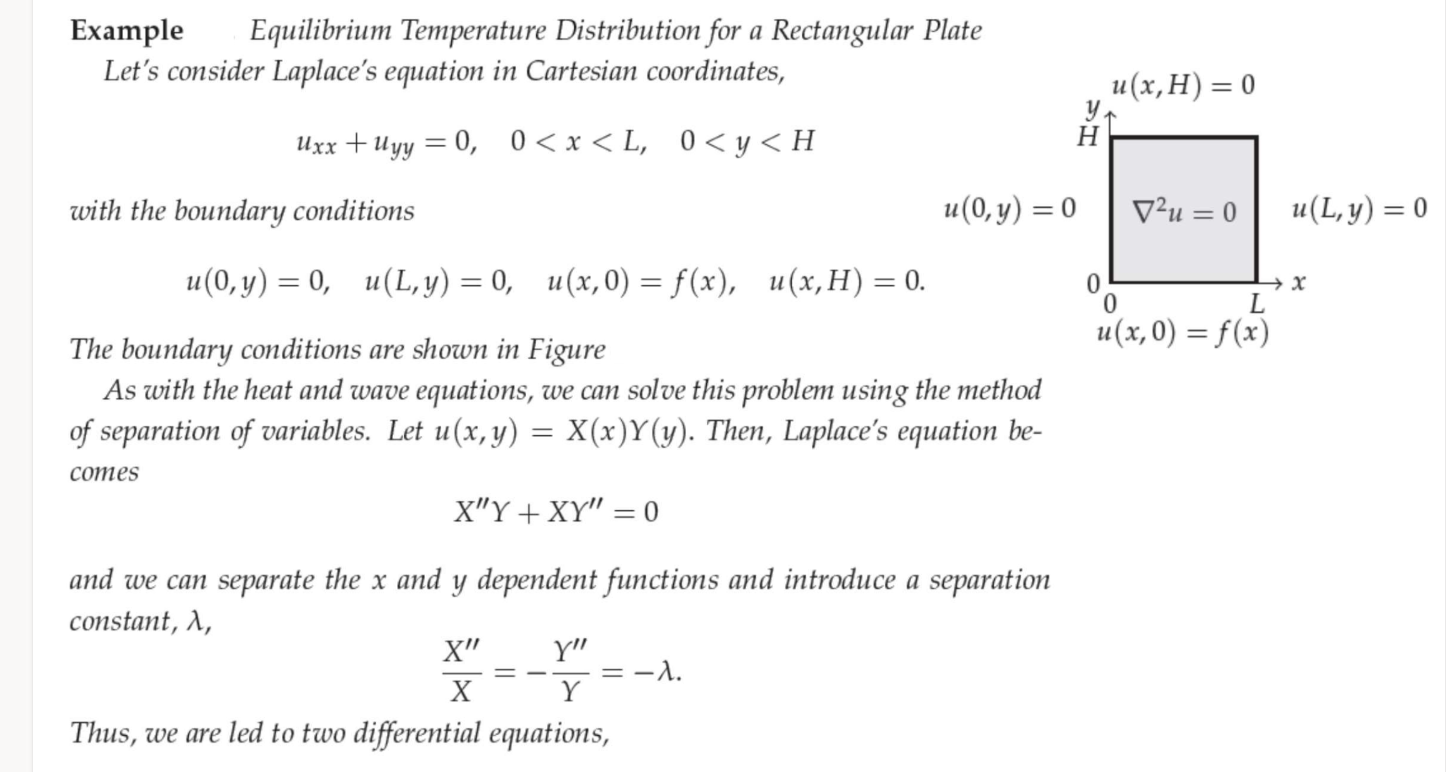

## **Separation part**

clear
clc
syms x t u(x,y) L H C1 y
assume ([L H],"positive")
LaplaceEq = diff(u,x,2) == -diff(u,y,2)

$$LaplaceEq(x, y) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,y\right)=-\frac{\partial^{2}}{\partial y^{2}}u\left(x,y\right)$$

x0 = u(0,y) == 0; xL = u(L,y) == 0;
y0 = u(x,0) == 0; yH = u(x,H) == 0;
syms X(x) Y(y)
SepVar = subs(LaplaceEq , u(x,y), X(x)*Y(y));

conditions

x0 = subs(x0,u(0,y),X(0))

$$x0 = X\left(0\right)=0$$

xL = subs(xL,u(L,y),X(L))

$$xL = X\left(L\right)=0$$

y0 = subs(y0,u(0,y),Y(0))

$$y0 = u\left(x,0\right)=0$$

yH = subs(yH,u(x,H),Y(H))

$$yH = Y\left(H\right)=0$$

Sepvar = SepVar/(X(x)*Y(y))

$$Sepvar(x, y) = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\frac{\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)}{Y\left(y\right)}$$

syms lambda
assume (lambda,"positive")

separation

var=children(Sepvar);
eqX = var(1) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

eqY = var(2) == -lambda^2

$$eqY = -\frac{\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)}{Y\left(y\right)}=-\lambda^{2}$$

X(x) = subs(dsolve(eqX,x0),str2sym('-C1'),sym('C2'))

$$X(x) = C_{2}\,\sin\left(\lambda \,x\right)$$

Y(y) = dsolve(eqY,yH)

$$Y(y) = C_{1}\,{\mathrm{e}}^{-\lambda \,y}-C_{1}\,{\mathrm{e}}^{-2\,H\,\lambda }\,{\mathrm{e}}^{\lambda \,y}$$

subY1 = expand(Y*exp(lambda*H))

$$subY1(y) = C_{1}\,{\mathrm{e}}^{H\,\lambda }\,{\mathrm{e}}^{-\lambda \,y}-C_{1}\,{\mathrm{e}}^{-H\,\lambda }\,{\mathrm{e}}^{\lambda \,y}$$

subY2 = subs(subY1,'C1',1)

$$subY2(y) = {\mathrm{e}}^{H\,\lambda }\,{\mathrm{e}}^{-\lambda \,y}-{\mathrm{e}}^{-H\,\lambda }\,{\mathrm{e}}^{\lambda \,y}$$

subY3 = subs(subY2,str2sym({'exp(lambda*H)*exp(-lambda*y)','exp(-lambda*H)*exp(lambda*y)',}),{exp(lambda*(H-y)),exp(-lambda*(H-y))})

$$subY3(y) = {\mathrm{e}}^{\lambda \,\left(H-y\right)}-{\mathrm{e}}^{-\lambda \,\left(H-y\right)}$$

subY4 = rewrite(subY3,"sinh");
sln = subs(X,x,L) == 0;

## **Find lambda**

[lambda,parameter,~] = solve(sln,lambda,"ReturnConditions",true)

$$lambda = \frac{\pi \,k}{L}$$

$$parameter = k$$

n = sym("n",["integer","positive"])

$$n = n$$

lambda = subs(lambda,parameter,n)

$$lambda = \frac{\pi \,n}{L}$$

Y(y) = subs(C1*exp(-lambda*H)*subY4,'lambda',lambda)

$$Y(y) = 2\,C_{1}\,{\mathrm{e}}^{-\frac{\pi \,H\,n}{L}}\,\sinh\left(\frac{\pi \,n\,\left(H-y\right)}{L}\right)$$

syms B_n ustruct(x,y);
Y(y) = subs(Y,str2sym({'C1','exp(-pi*H*n/L)'}),{1/2,1})

$$Y(y) = \sinh\left(\frac{\pi \,n\,\left(H-y\right)}{L}\right)$$

X(x) = subs(X,{'C2','lambda'},{B_n,lambda})

$$X(x) = B_{n}\,\sin\left(\frac{\pi \,n\,x}{L}\right)$$

ustruct(x,y) = X(x)*Y(y)

$$ustruct(x, y) = B_{n}\,\sin\left(\frac{\pi \,n\,x}{L}\right)\,\sinh\left(\frac{\pi \,n\,\left(H-y\right)}{L}\right)$$

## **Fourier series part**

syms Sigma
f(x) = (x-0.5)^2;
ceff =subs(coeffs(ustruct(x,0),sin(pi*n*x/L)),sym('B_n'),1)

$$ceff = \sinh\left(\frac{\pi \,H\,n}{L}\right)$$

Bn = 2/L*int(f*sin(pi*n*x/L),x,[0 L])/ceff

$$Bn = -\frac{2\,\left(\frac{\pi \,L\,n\,\left(4\,L\,\sin\left(\pi \,n\right)-8\,L^{2}\,\sin\left(\pi \,n\right)\right)}{4}-\frac{L\,\left(8\,L^{2}\,\cos\left(\pi \,n\right)-8\,L^{2}\right)}{4}+\frac{L\,n^{2}\,\pi^{2}\,\left(4\,\cos\left(\pi \,n\right)\,L^{2}-4\,\cos\left(\pi \,n\right)\,L+\cos\left(\pi \,n\right)-1\right)}{4}\right)}{L\,n^{3}\,\pi^{3}\,\sinh\left(\frac{\pi \,H\,n}{L}\right)}$$

Bn = subs(Bn,{L,H},{1,1})

$$Bn = \frac{2\,\left(2\,\cos\left(\pi \,n\right)+\pi \,n\,\sin\left(\pi \,n\right)-\frac{n^{2}\,\pi^{2}\,\left(\cos\left(\pi \,n\right)-1\right)}{4}-2\right)}{n^{3}\,\pi^{3}\,\sinh\left(\pi \,n\right)}$$

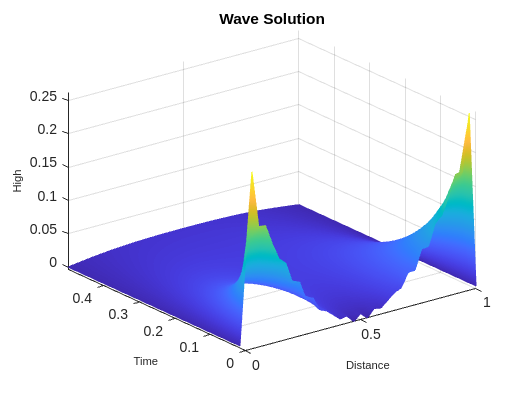

Sol = symsum(subs(ustruct,{B_n,L,H},{Bn,1,1}),n,1,30);
clf;figure
fsurf(Sol,[0 1 0 0.5],"EdgeColor","interp")
title("Wave Solution")
xlabel('Distance','FontSize',8)
ylabel('Time','FontSize',8)
zlabel('High','FontSize',8) 